# LAB1 MATLAB Programming

李志颖 12210309  夏琮杰12210520

## Introduction

## Results and Analysis

## 1.4

### (a)

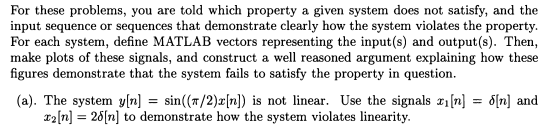

Initialize.

clear; clc; close all;

Create two vectors x1 and x2 and plot them

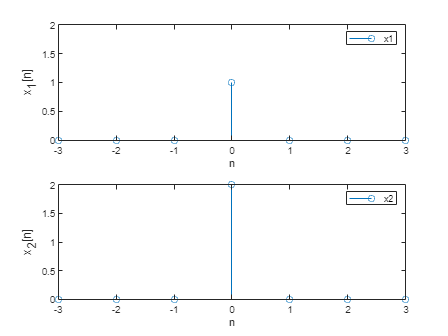

n=-3:3;
x1=(n==0);
x2=2*x1;
figure;
subplot(2,1,1);
stem(n,x1);
xlabel('n');ylabel('x_1[n]');
legend('x1');
axis([xlim,0 2])
subplot(2,1,2);
stem(n,x2);
xlabel('n');ylabel('x_2[n]');
legend('x2');
axis([xlim,0 2]);

Calculate y1 and y2 and plot them

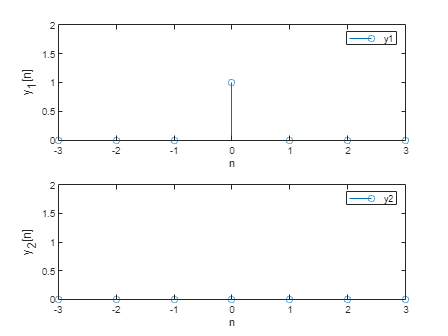

y1=sin(pi*x1/2);
y2=sin(pi*x2/2);
figure;
subplot(2,1,1);
stem(n,y1);
xlabel('n');ylabel('y_1[n]');
legend('y1');
axis([xlim,0 2]);
subplot(2,1,2);
stem(n,y2);
xlabel('n');ylabel('y_2[n]');
legend('y2');
axis([xlim,0 2]);

From the two figures, we can see that x2 = 2x1,but y2 ≠ 2y1..

According to the definition, the system is not linear 

### (b)

Initialize.

clear; clc; close all;

Create x[n] ,x[n+1] and y[n] and plot x[n] and y[n]

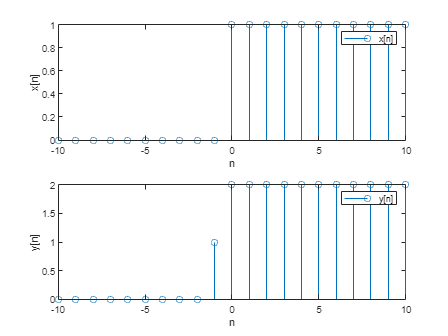

n=-10:10;
x1=(n>=0);
x2=(n>=-1);
y=x1+x2;
subplot(2,1,1);
stem(n,x1);
xlabel('n');ylabel('x[n]')
legend('x[n]')
subplot(2,1,2);
stem(n,y);
xlabel('n');ylabel('y[n]')
legend('y[n]')

As can be seen from the above figure, the signal at n=-1 is affected by n=0,

According to the definition,  the system is not causal.

### (c)(d)

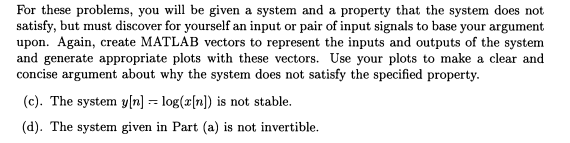

Initialize.

clear; clc; close all;

（c）We choose x[n]=$\frac{1}{n}$ as the input function.  Then we create x[n] and calculate y[n] and plot them

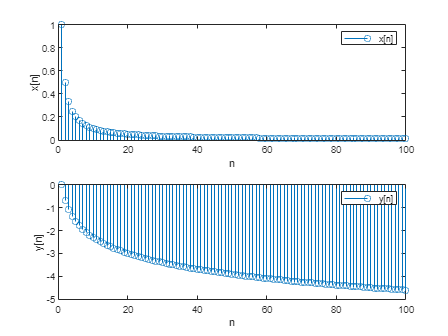

n=1:100;
x=1./n;
y=log(x);
subplot(2,1,1);
stem(n,x);
xlabel('n');ylabel('x[n]')
legend('x[n]');
subplot(2,1,2);
stem(n,y);
xlabel('n');ylabel('y[n]');
legend('y[n]')

When x[n] tends to 0, y[n] tends to negative infinity,

According to the definition, the system is unstable.

Initialize.

clear; clc; close all;

(d)We choose x[n]=$n$ as the input function.Then we create x[n] and calculate y[n] and plot them.

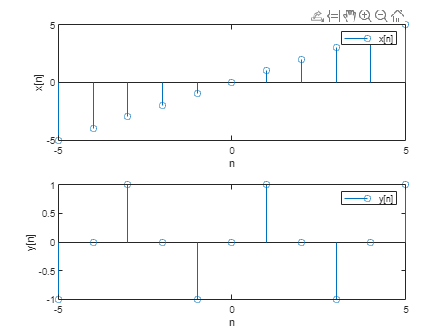

n=-5:5;
x=n;
y=sin(pi*x/2);
subplot(2,1,1);
stem(n,x);
xlabel('n');ylabel('x[n]');
legend('x[n]');
subplot(2,1,2);
stem(n,y);
xlabel('n');ylabel('y[n]');
legend('y[n]');

The same output corresponds to more than one input, 

According to the definition, the system is irreversible.

## 1.5

### (a)

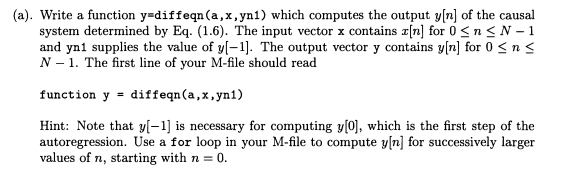

Initialize.

clear; clc; close all;

We use the variable k to replace the variable n. Then we can make the function y(k) which is one unit on the right of the y(n) on graph. So we can gain the f(n).

% function y = diffeqn(a,x,yn1)
% N = length(x);
% y = zeros(1,N);
% y(1) = a * yn1 + x(1);
% for n = 2:N
%     y(n) = a * y(n-1) + x(n);
% end
% end


### (b)

Initialize.

clear; clc; close all;

Using the function of (a), when a=1, yn1=0, the plot of y[k] is shown.

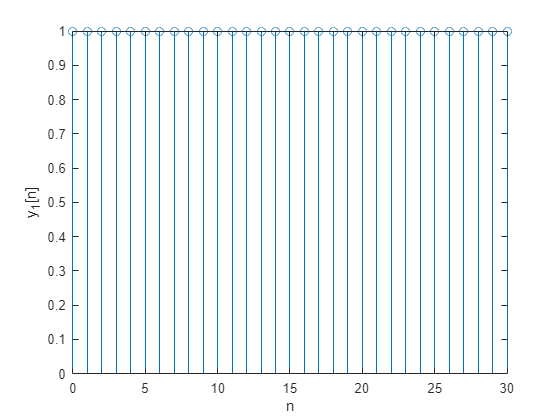

n=0:30;
x1=(n==0);
yn1=0;a=1;
y1=diffeqn(a,x1,yn1);
stem(n,y1);
xlabel('n')
ylabel('y_1[n]')

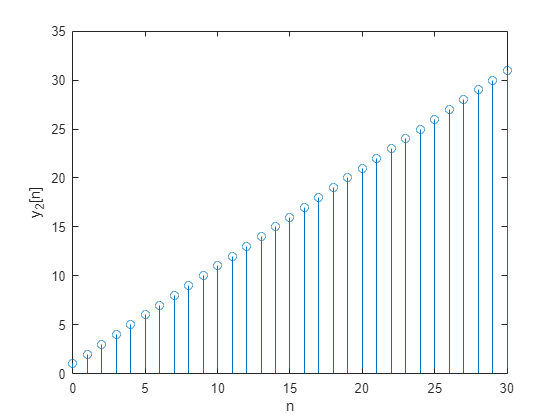


x2=(n>=0);
y2=diffeqn(a,x2,yn1);
stem(n,y2);
xlabel('n')
ylabel('y_2[n]')

### (c)

Initialize.

clear; clc; close all;

Using the function of(a), when a=1, yn1=-1, x1[n]=u[n] and x2[n]=2u[n]. We can plot y1[n], y2[n] and (2y1[n]-y2[n]).

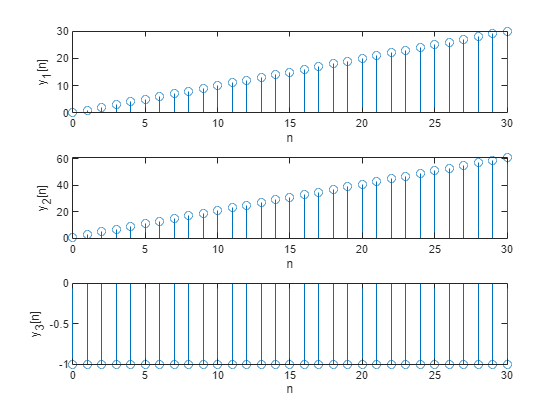

n=0:30;
a=1;yn1=-1;
x1=(n>=0);
x2=2*x1;
y1=diffeqn(a,x1,yn1);
y2=diffeqn(a,x2,yn1);
y3=2*y1-y2;
subplot(3,1,1);
stem(n,y1);
xlabel('n');
ylabel('y_1[n]')
subplot(3,1,2);
stem(n,y2);
xlabel('n');
ylabel('y_2[n]')
subplot(3,1,3);
stem(n,y3);
xlabel('n');
ylabel('y_3[n]')

When y[-1]=-1 and x1[n]=u[n], y[0]=0. When x2[n]=2u[n], y[0]=1. On the basis of y[n]=ay[n-1]+x[n]. When x1[n]=u[n], y1[n]=n. When x2[n]=2u[n], y2[n]=2n+1. So 2y1[n]-y2[n]=-1 instead of 0.

## Function

function y = diffeqn(a,x,yn1)
N = length(x);
y = zeros(1,N);
y(1) = a * yn1 + x(1);
for n = 2:N
    y(n) = a * y(n-1) + x(n);
end
end

## Expeience

(1)We deepened our understanding of matlab and became proficient in its basic syntax and used it to draw diagrams

(2)We learned to use functions to answer questions

(3)We were able to debug our own code based on Matlab's prompts.

(4)We had a primer on matlab code representation of signals and systems and deepened understanding of unit impulse functions and unit step functions.

(5)We also learned more about the characteristics of the system as we wrote the code.

(6)In real-time scripts, functions go at the end of the line.

(7)Collaboration is important, and discussions with peers lead to more accurate answers.

(8)Use github to manage group code for easy team cooperation.